**Preprocess data**

Since the data we have recorded comes in a single CSV file, with all the signals one right after the other, it is necesarry to split them individually, in order to prepare them for training and testing.

Let´s begin with plotting a raw file, to see what we get

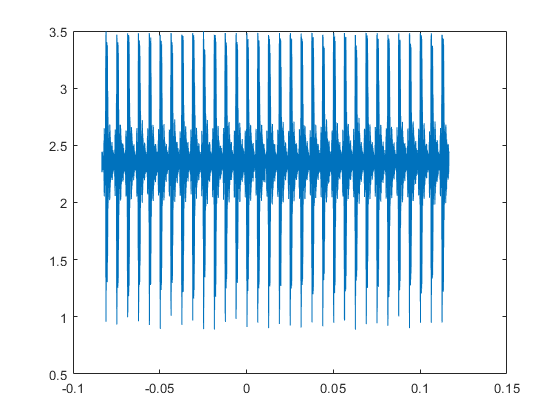

    data = readtable('./Data/0cm/scope_11.csv', 'HeaderLines',1);
    figure
    plot( data.second, data.Volt )

So, from the figure, we have approximately  32 different signals, with a length of approximatelly 6.245ms. We can get the sample time (Ts) from the data.second variable

    Ts = data.second(2)-data.second(1)

Ts = 3.1000e-06

With this data, we could calculate the length of a single signal measured in "samples", by dividing the total length of the signal by the sample time

    T = 6245e-6;
    len = round(T/Ts)

len = 2015

We can now write a function that receives a file and returns a table (and maybe a MAT file to save the data for future projects). The table will be of lenx32, per file. Every single column of that table will represent a single signal. The function is inside the data_split.m file

Now, let's preprocess the **data for 0cm**

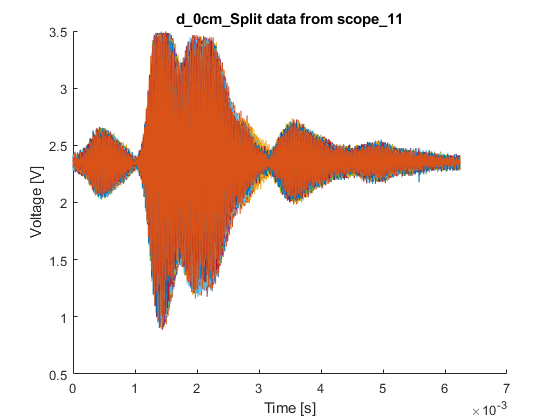

    % Let's begin with the 0cm data, let's create a table for each file
    A = data_split('./Data/0cm/scope_11.csv', 'd_0cm_', 0, 6245e-6, -0.082448298);

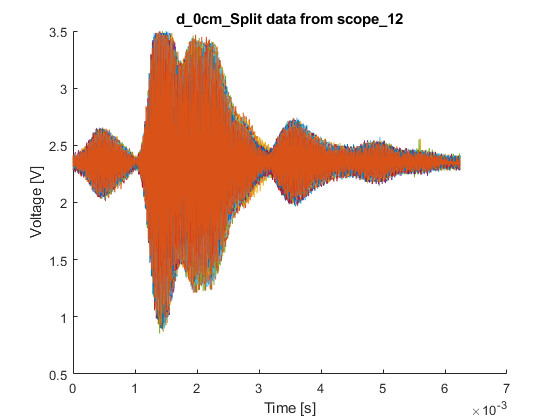

    B = data_split('./Data/0cm/scope_12.csv', 'd_0cm_', 30, 6245e-6, -0.082448298);

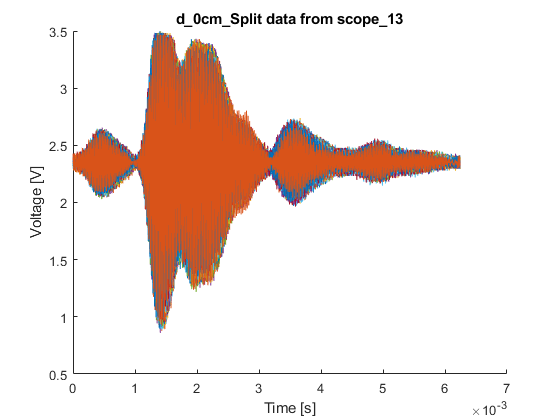

    C = data_split('./Data/0cm/scope_13.csv', 'd_0cm_', 60, 6245e-6, -0.082448298);

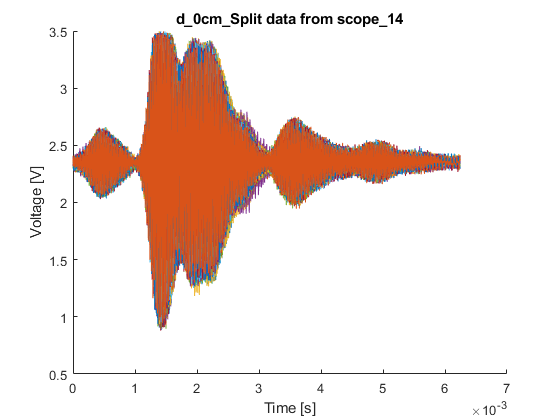

    D = data_split('./Data/0cm/scope_14.csv', 'd_0cm_', 90, 6245e-6, -0.082448298);

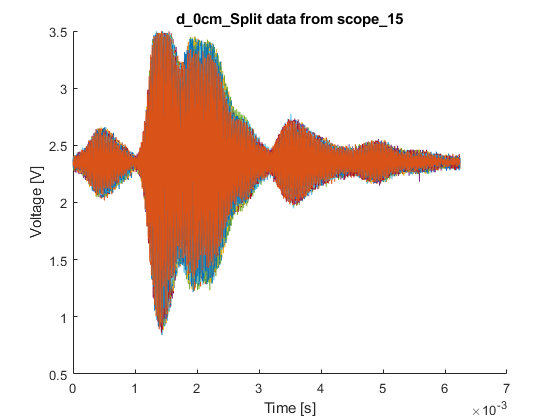

    E = data_split('./Data/0cm/scope_15.csv', 'd_0cm_', 120, 6245e-6, -0.082448298);

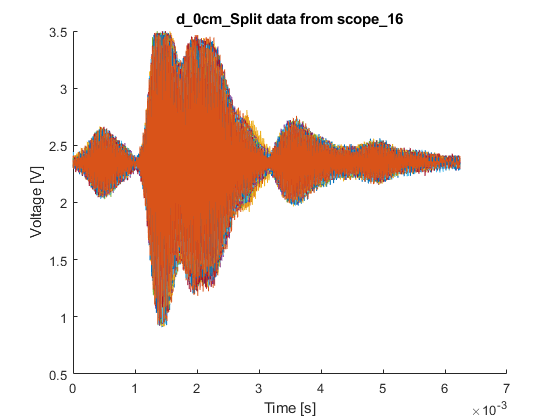

    F = data_split('./Data/0cm/scope_16.csv', 'd_0cm_', 150, 6245e-6, -0.082448298);

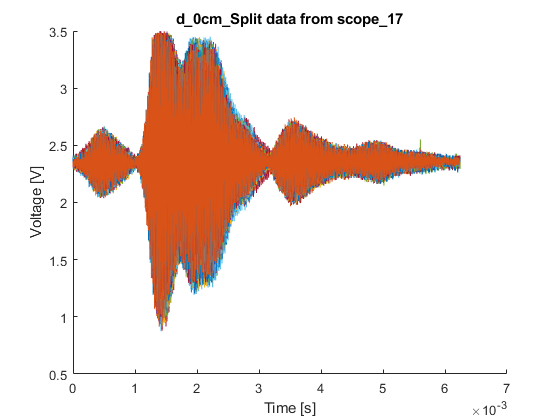

    G = data_split('./Data/0cm/scope_17.csv', 'd_0cm_', 180, 6245e-6, -0.082448298);

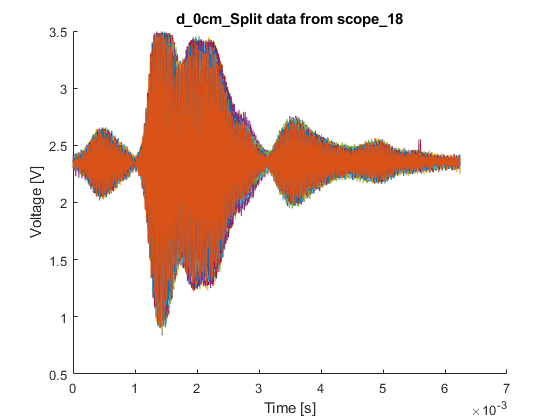

    H = data_split('./Data/0cm/scope_18.csv', 'd_0cm_', 210, 6245e-6, -0.082448298);

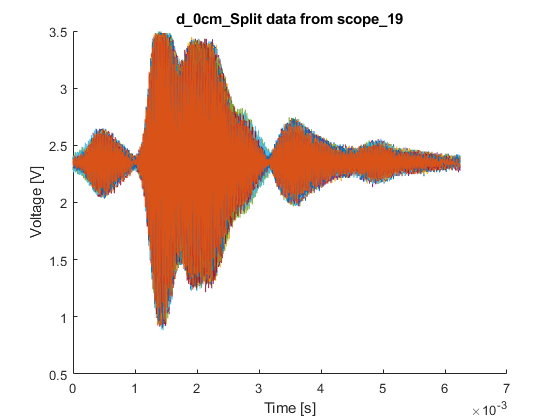

    I = data_split('./Data/0cm/scope_19.csv', 'd_0cm_', 240, 6245e-6, -0.082448298);

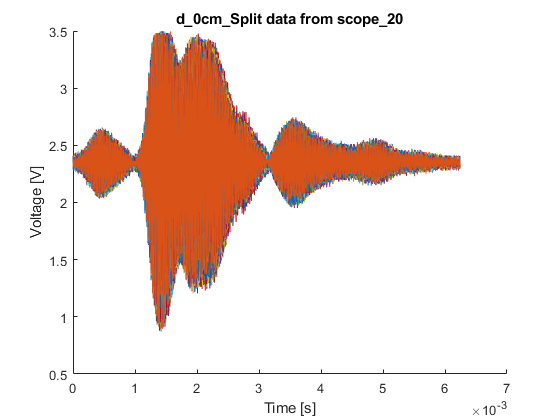

    J = data_split('./Data/0cm/scope_20.csv', 'd_0cm_', 270, 6245e-6, -0.082448298);

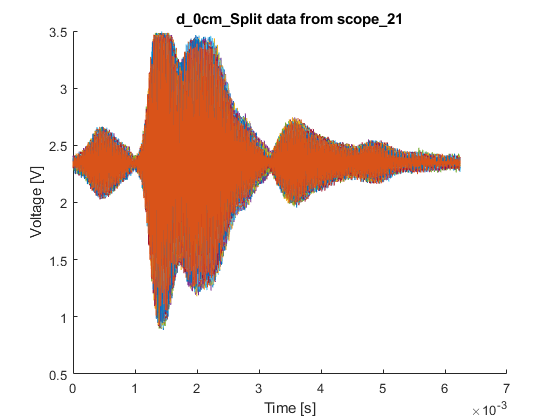

    K = data_split('./Data/0cm/scope_21.csv', 'd_0cm_', 300, 6245e-6, -0.082448298);

Now we can concatenate the tables to get a single Train table, and a Test table, like this:

    % Create tables to train and test
    Train_0cm = [A, B, C, D, E, F, G, H];
    Test_0cm = [ I, J, K ];
    
    % Save them as MAT for later
    save('./Data/0cm/Train_0cm.mat', 'Train_0cm')
    save('./Data/0cm/Test_0cm.mat', 'Test_0cm')

We have our test data, but we're still missing the labels.

    % Get the length of the test table
    [ ~ , n ] = size(Test_0cm);
    
    % Initialize a structure with a field Y, full of 0s, since this dataset is for 0cm.
    temp.Y = zeros(n,1);
    % Turn it into a table
    Y_Test_0cm = struct2table(temp);
    
    % Same forthe Train data
    [ ~ , n ] = size(Train_0cm);
    temp.Y = zeros(n,1);
    Y_Train_0cm = struct2table(temp);
    
    % Save them as MAT for later
    save('./Data/0cm/Y_Train_0cm.mat', 'Y_Train_0cm')
    save('./Data/0cm/Y_Test_0cm.mat', 'Y_Test_0cm')

We need now to repeat the process for the rest of the datasets: 2cm, 4cm and 6cm.

**2cm Data**

In case you're wondering how I got the "-0.095110298" time: I just zoomed in ont he plot until I got a value that could be found using *find(data.second == t).* I know, not fancy, but it works.

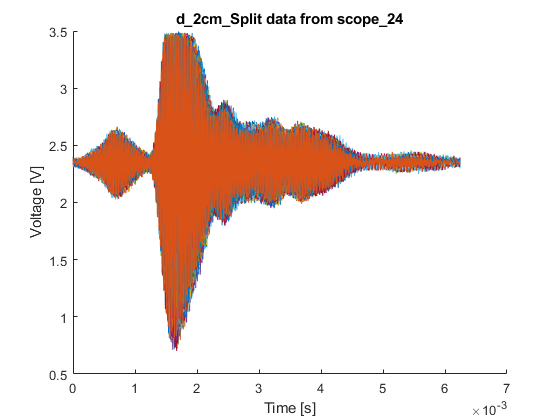

    % Get tables with data, it does not matter if we overwerite the data, we have it saved as MAT
    A = data_split('./Data/2cm/scope_24.csv', 'd_2cm_', 0, 6245e-6, -0.095110298);

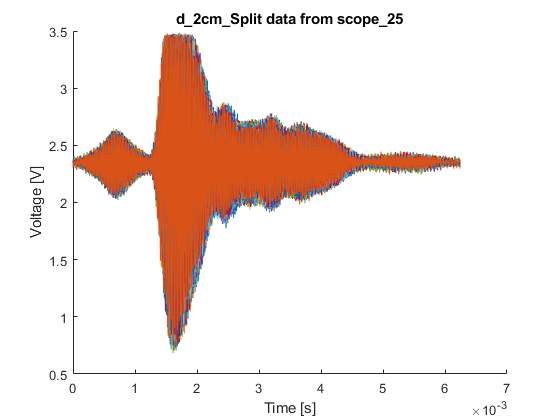

    B = data_split('./Data/2cm/scope_25.csv', 'd_2cm_', 30, 6245e-6, -0.095110298);

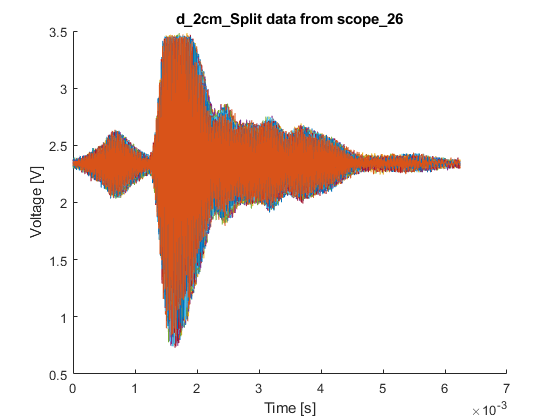

    C = data_split('./Data/2cm/scope_26.csv', 'd_2cm_', 60, 6245e-6, -0.095110298);

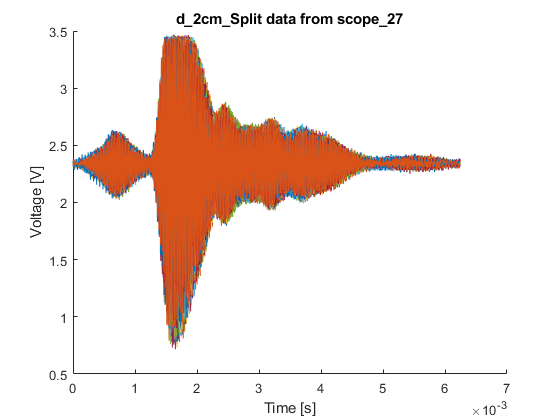

    D = data_split('./Data/2cm/scope_27.csv', 'd_2cm_', 90, 6245e-6, -0.095110298);

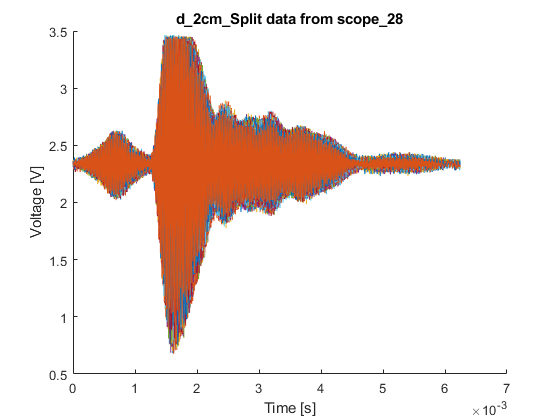

    E = data_split('./Data/2cm/scope_28.csv', 'd_2cm_', 120, 6245e-6, -0.095110298);

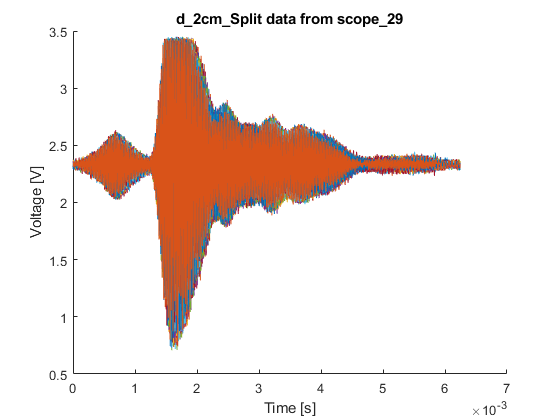

    F = data_split('./Data/2cm/scope_29.csv', 'd_2cm_', 150, 6245e-6, -0.095110298);

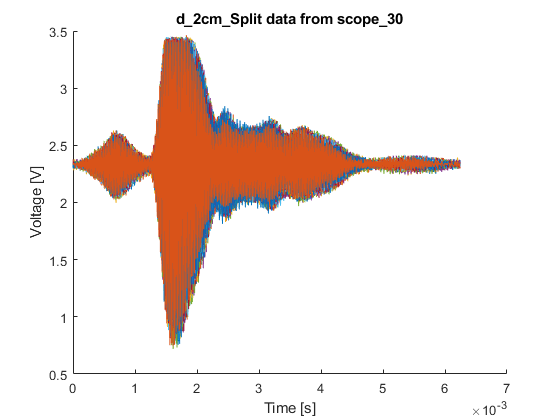

    G = data_split('./Data/2cm/scope_30.csv', 'd_2cm_', 180, 6245e-6, -0.095110298);

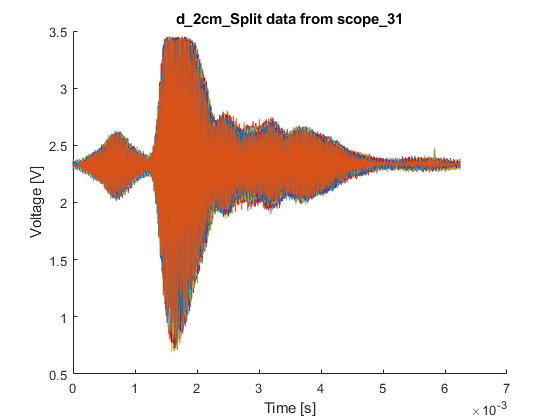

    H = data_split('./Data/2cm/scope_31.csv', 'd_2cm_', 210, 6245e-6, -0.095110298);

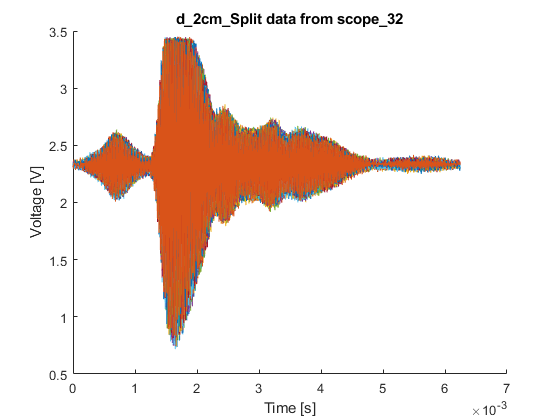

    I = data_split('./Data/2cm/scope_32.csv', 'd_2cm_', 240, 6245e-6, -0.095110298);

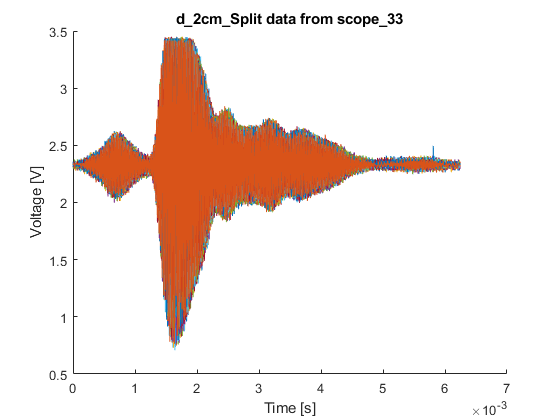

    J = data_split('./Data/2cm/scope_33.csv', 'd_2cm_', 270, 6245e-6, -0.095110298);

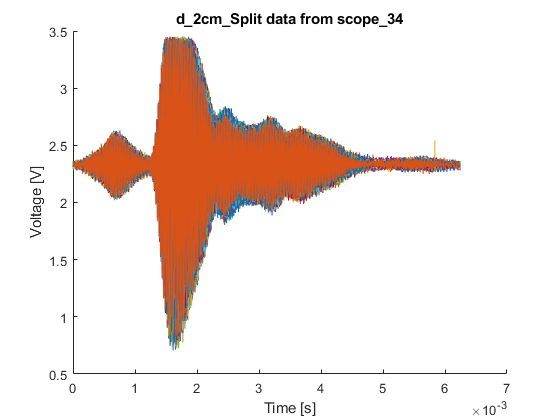

    K = data_split('./Data/2cm/scope_34.csv', 'd_2cm_', 300, 6245e-6, -0.095110298);

    
    % Create tables to train and test
    Train_2cm = [A, B, C, D, E, F, G, H];
    Test_2cm = [ I, J, K ];
    
    % Save them as MAT for later
    save('./Data/2cm/Train_2cm.mat', 'Train_2cm')
    save('./Data/2cm/Test_2cm.mat', 'Test_2cm')
    
    % Make tags - NOTICE THESE ARE NOT 0s, WE HAVE 2s
    [ ~ , n ] = size(Test_2cm);
    temp.Y = 2*ones(n,1);
    Y_Test_2cm = struct2table(temp);
    
    [ ~ , n ] = size(Train_2cm);
    temp.Y = 2*ones(n,1);
    Y_Train_2cm = struct2table(temp);
    
    % Save them as MAT for later
    save('./Data/2cm/Y_Train_2cm.mat', 'Y_Train_2cm')
    save('./Data/2cm/Y_Test_2cm.mat', 'Y_Test_2cm')

**4cm Data**

Same here, maybe I should have written a function for this.

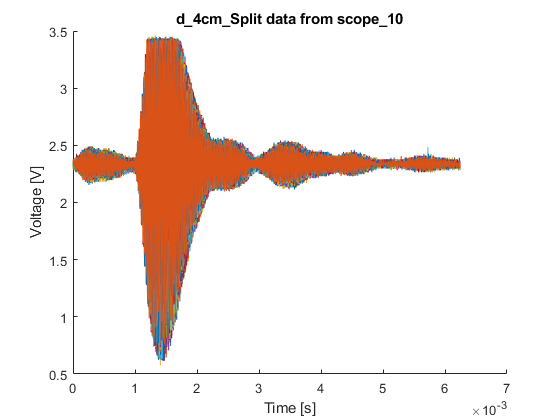

    % Get tables with data
    A = data_split('./Data/4cm/scope_10.csv', 'd_4cm_', 0,  6245e-6, -0.094854697000000);

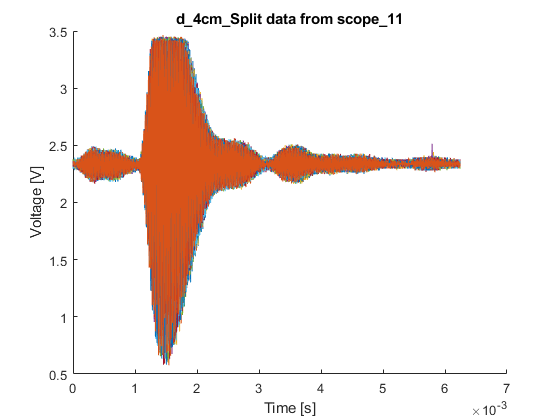

    B = data_split('./Data/4cm/scope_11.csv', 'd_4cm_', 30, 6245e-6,  -0.095053097000000);

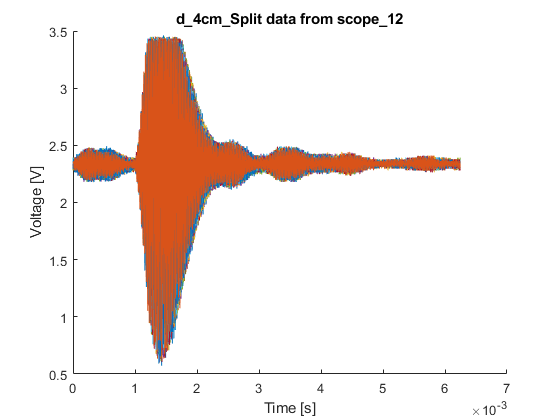

    C = data_split('./Data/4cm/scope_12.csv', 'd_4cm_', 60, 6245e-6,  -0.094854697000000);

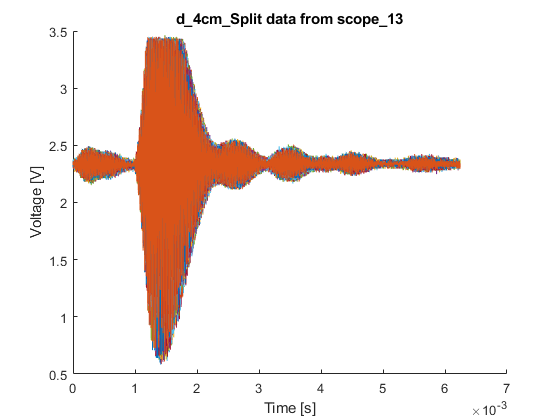

    D = data_split('./Data/4cm/scope_13.csv', 'd_4cm_', 90, 6245e-6,  -0.094854697000000);

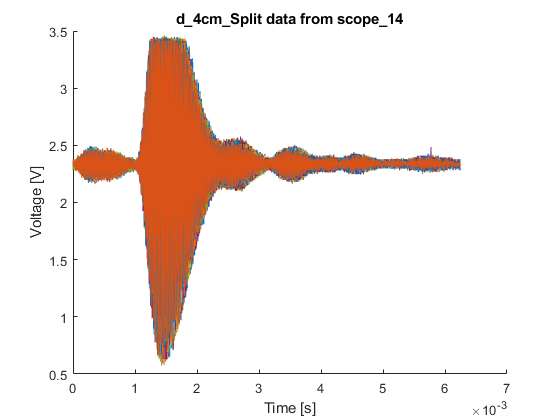

    E = data_split('./Data/4cm/scope_14.csv', 'd_4cm_', 120, 6245e-6,  -0.095053097000000);

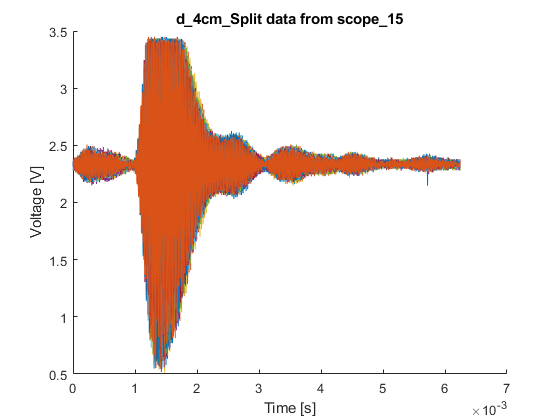

    F = data_split('./Data/4cm/scope_15.csv', 'd_4cm_', 150, 6245e-6,  -0.094854697000000);

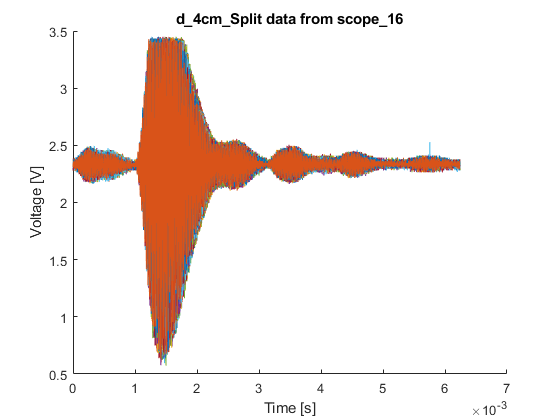

    G = data_split('./Data/4cm/scope_16.csv', 'd_4cm_', 180, 6245e-6,  -0.095580098000000);

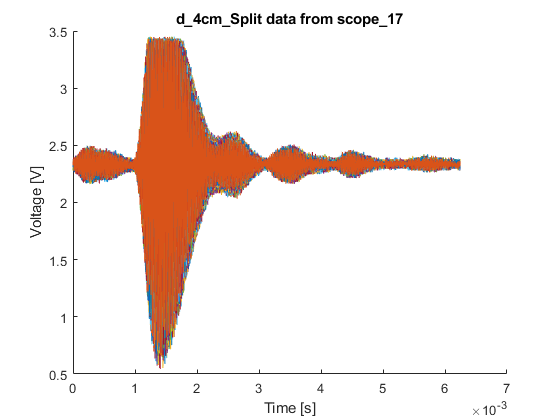

    H = data_split('./Data/4cm/scope_17.csv', 'd_4cm_', 210, 6245e-6,  -0.094854697000000);

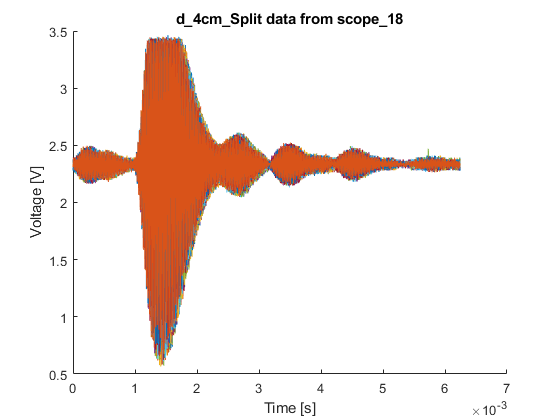

    I = data_split('./Data/4cm/scope_18.csv', 'd_4cm_', 240, 6245e-6,  -0.094854697000000);

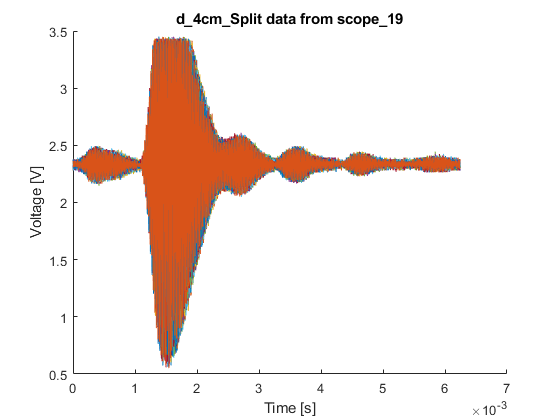

    J = data_split('./Data/4cm/scope_19.csv', 'd_4cm_', 270, 6245e-6,  -0.095518098000000);

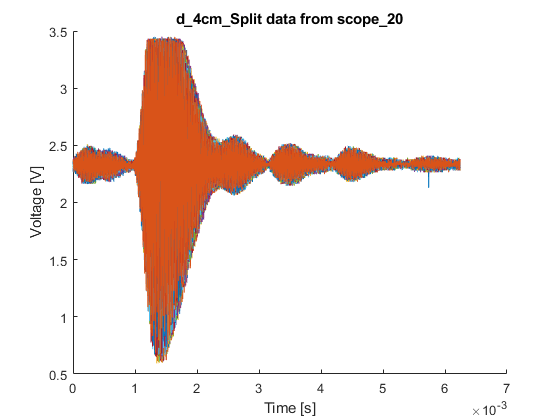

    K = data_split('./Data/4cm/scope_20.csv', 'd_4cm_', 300, 6245e-6,  -0.094854697000000);

    
    % Create tables to train and test
    Train_4cm = [A, B, C, D, E, F, G, H];
    Test_4cm = [ I, J, K ];
    
    % Save them as MAT for later
    save('./Data/4cm/Train_4cm.mat', 'Train_4cm')
    save('./Data/4cm/Test_4cm.mat', 'Test_4cm')
    
    % Make tags
    [ ~ , n ] = size(Test_4cm);
    temp.Y = 4*ones(n,1);
    Y_Test_4cm = struct2table(temp);
    
    [ ~ , n ] = size(Train_4cm);
    temp.Y = 4*ones(n,1);
    Y_Train_4cm = struct2table(temp);
    
    % Save them as MAT for later
    save('./Data/4cm/Y_Train_4cm.mat', 'Y_Train_4cm')
    save('./Data/4cm/Y_Test_4cm.mat', 'Y_Test_4cm')

**6cm Data**

Same

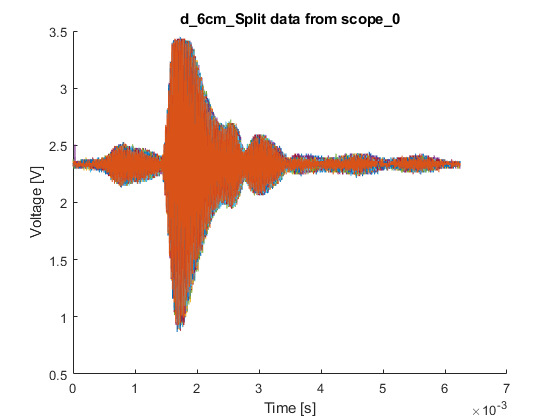

    % Get tables with data
    A = data_split('./Data/6cm/scope_0.csv', 'd_6cm_', 0, 6245e-6, -0.095281096000000);

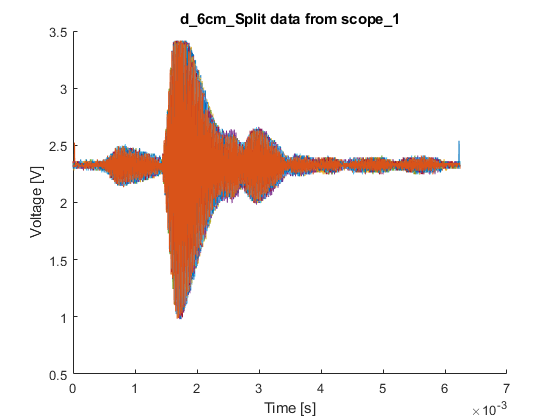

    B = data_split('./Data/6cm/scope_1.csv', 'd_6cm_', 30, 6245e-6, -0.095281096000000);%

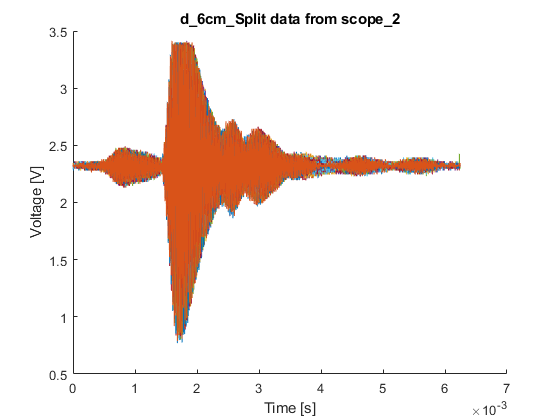

    C = data_split('./Data/6cm/scope_2.csv', 'd_6cm_', 60, 6245e-6, -0.095281096000000);

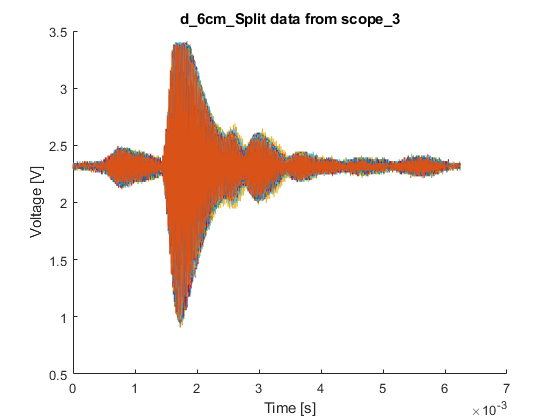

    D = data_split('./Data/6cm/scope_3.csv', 'd_6cm_', 90, 6245e-6, -0.095281096000000);

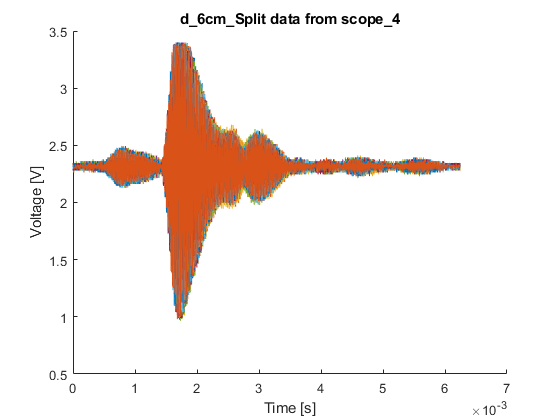

    E = data_split('./Data/6cm/scope_4.csv', 'd_6cm_', 120, 6245e-6, -0.095281096000000);%

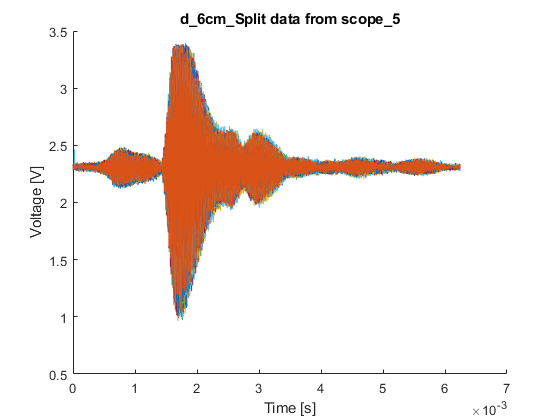

    F = data_split('./Data/6cm/scope_5.csv', 'd_6cm_', 150, 6245e-6, -0.095791097000000);

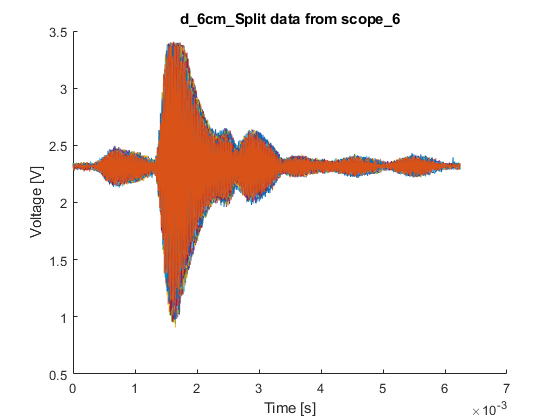

    G = data_split('./Data/6cm/scope_6.csv', 'd_6cm_', 180, 6245e-6, -0.095171096000000);%%

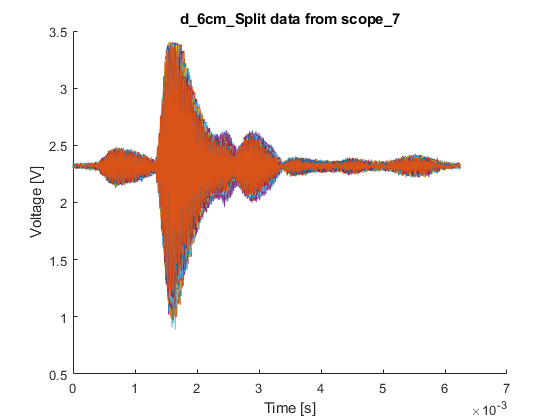

    H = data_split('./Data/6cm/scope_7.csv', 'd_6cm_', 210, 6245e-6, -0.095171096000000);

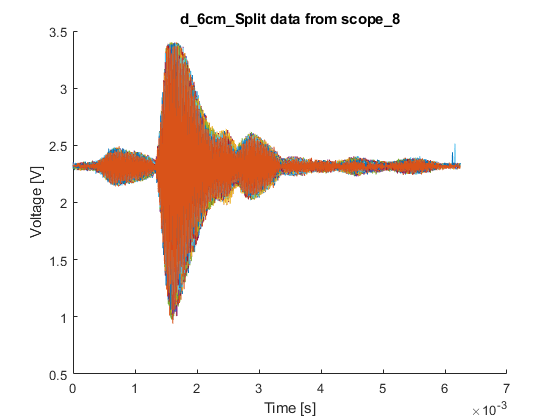

    I = data_split('./Data/6cm/scope_8.csv', 'd_6cm_', 240, 6245e-6, -0.095171096000000);

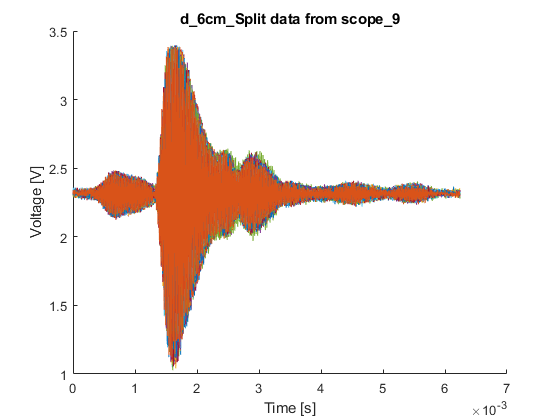

    J = data_split('./Data/6cm/scope_9.csv', 'd_6cm_', 270, 6245e-6, -0.095171096000000);%%

    
    
    % Create tables to train and test
    Train_6cm = [A, B, C, D, E, F, G, H];
    Test_6cm = [ I, J];
    
    % Save them as MAT for later
    save('./Data/6cm/Train_6cm.mat', 'Train_6cm')
    save('./Data/6cm/Test_6cm.mat', 'Test_6cm')
    
    % Make tags
    [ ~ , n ] = size(Test_6cm);
    temp.Y = 6*ones(n,1);
    Y_Test_6cm = struct2table(temp);
    
    [ ~ , n ] = size(Train_6cm);
    temp.Y = 6*ones(n,1);
    Y_Train_6cm = struct2table(temp);
    
    % Save them as MAT for later
    save('./Data/6cm/Y_Train_6cm.mat', 'Y_Train_6cm')
    save('./Data/6cm/Y_Test_6cm.mat', 'Y_Test_6cm')

**Load training data**

    load('Data/0cm/Train_0cm.mat')
    load('Data/0cm/Y_Train_0cm.mat')
    load('Data/2cm/Train_2cm.mat')
    load('Data/2cm/Y_Train_2cm.mat')
    load('Data/4cm/Train_4cm.mat')
    load('Data/4cm/Y_Train_4cm.mat')
    load('Data/6cm/Train_6cm.mat')
    load('Data/6cm/Y_Train_6cm.mat')
    
    % Append tables to make a single one
    train = [Train_0cm, Train_2cm, Train_4cm, Train_6cm];
    y_train = [Y_Train_0cm; Y_Train_2cm; Y_Train_4cm; Y_Train_6cm];


Create cell array and make a classifier vector

    n = width( train );
    
    x = cell( n, 1 );
    % create cell
    for k = 1:n
        x{ k , 1 }  = table2array( train( : , k ) );
    end
    
    % Now create categorical array for classifier
    y = categorical( table2array( y_train(:,:) ) );
    t = linspace(0,10,height(train));

See the data in different colors, depending on their classification

    figure
    for k = 1:n
        switch double( y(k) )
            case 1
                colr = [1 0 0];
            case 2
                colr = [0 1 0];
            case 3
                colr = [0 0 1];
            case 4
                colr = [0 0 0];
        end
                
        plot(t, x{k,:}, 'color', colr)
        hold on
    end
    title('Training set observation')
    xticklabels('auto')
    xlabel('Samples [x1000]')
    ylabel('Voltage [V]')

Sort data by length

    numElem = numel(x);
    
    % Preallocate size
    sequenceLengths = zeros(1, numElem);
    
    % Get all lengths
    for k=1:numElem
        sequence = x{k};
        sequenceLengths(k) = size(sequence,1);
    end
    
    %Sort the data by sequence length.
    [sequenceLengths,idx] = sort(sequenceLengths);
    X = x(idx);
    Y = y(idx);

View data by length, in our case, all of them are the same, but, still useful for other applications.

    figure
    bar(sequenceLengths)
    xlabel('Signal')
    ylabel('Length')
    title('Signal Lengths')

## Define LSTM Network Architecture

Define the LSTM network architecture. Specify the input size to be sequences of size 1 (the dimension of the input data). Specify an LSTM layer with an output size of 100, and output the last element of the sequence. Finally, specify classes by including a fully connected layer of size 2, followed by a softmax layer and a classification layer.

    inputSize = 2016;
    outputSize = 100;
    outputMode = 'last';
    numClasses = 4;
    
    layers = [ ...
        sequenceInputLayer(inputSize)
        lstmLayer(outputSize,'OutputMode',outputMode)
        fullyConnectedLayer(numClasses)
        softmaxLayer
        classificationLayer]

Undefined function 'sequenceInputLayer' for input arguments of type 'double'.

Now, specify the training options. Choose a mini-batch size of 20 to reduce the amount of padding in the mini-batches. Set the maximum number of epochs to 50, and specify to not shuffle the data.

    maxEpochs = 100;
    miniBatchSize = 20;
    shuffle = 'once'; % Shuffle the training and validation data once before training.
    
    options = trainingOptions('sgdm', ...
        'MaxEpochs',maxEpochs, ...
        'MiniBatchSize',miniBatchSize, ...
        'LearnRateSchedule','piecewise', ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateDropPeriod',10, ...
        'Shuffle', shuffle);

## Train LSTM Network

Train the LSTM network with the specified training options by using `trainNetwork`.

    net = trainNetwork(X,Y,layers,options);

**Test the network**

The LSTM network `net` was trained using mini-batches of sequences of similar length. Ensure that the test data is organized in the same way. Sort the test data by sequence length.

    load('Data/0cm/Test_0cm.mat')
    load('Data/0cm/Y_Test_0cm.mat')
    load('Data/2cm/Test_2cm.mat')
    load('Data/2cm/Y_Test_2cm.mat')
    
    
    % Append tables to make a single one
    tst = [Test_0cm, Test_2cm];
    y_test = [Y_Test_0cm; Y_Test_2cm];
    
    n = width( tst );
    
    x_test = cell( n, 1 );
    % create cell
    for k = 1:n
        x_test{ k , 1 }  = table2array( tst( : , k ) );
    end
    
    
    % Now create categorical array for classifier
    y_test = categorical( table2array( y_test(:,:) ) );

Classify the test data. To reduce the amount of padding introduced by the classification process, set the mini-batch size to 20.

    miniBatchSize = 20;
    YPred = classify(net,x_test, ...
        'MiniBatchSize',miniBatchSize);

Calculate the classification accuracy of the predictions.

    acc = sum(YPred == y_test)./numel(y_test)

That's it.